CODE ADDITIONS 

7/8/2026; 7:53 pm (Isaac)

- Implemented an image processing algorithm that (mostly) works for Tube images. It needs testing.

7/9/2026; 4:34 pm (Ryan)

- Updated Dataset organization so that each subfolders organization matches. Changed to imageDatastore and added class labels and pass/fail classification for each image.

7/11/2026; 4:14 pm (Ryan)

- Added corner removal to improve output decision reliability. Added comments to better explain which image is which when selected from the range (Tubes only).

7/12/2026; 10:52 am (Ryan)

- Added labels to ROI that correspond to each table entry for easier analysis of performance. Adjusted minimum eccentricity to improve detection of short tubes as anomalous.

7/16/2026; 4:06 pm (Ryan)

- Adjusted the singleimageinspectionfunction to run without displaying output, allowing for faster results to be gathered for batch processing. Basic batch processing implemented, will need further improvements. Corrected some program errors. 

7/19/2026; 11:04 am (Ryan)

- Added yield and defect rates and also a pass/fail confusion matrix

Choose Data Subset of Interest, Adjust Parameters

dataSubset = "tubes";
displayOrginalImage =false;
displayClassicalInspectionData =false;
useAIClassifier =true;

performBatchTesting =true;

Current working algorithm

% Obtain the file location of the dataset. 
% ***IMPORTANT***
% This file location stored is a RELATIVE path!!!
% For this script to run, your active path must be set to where
% the MPDD dataset is stored on your local system.
%
% To change your active path, click the "Set Path" option under the
% "Environment" sub tab within the MATLAB application. 
fileLoc = sprintf("MPDD/%s", dataSubset);


% Creates an image Datastore to store all images of specified subset type.
% The image Datastore is setup to specifically look for images with certain file
% extensions that are common for images (i.e. jpg, png, etc.)
ds = imageDatastore(fileLoc, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);

% Filter 'ground truth'/masks that are only used for model verification
excludeMask = contains(ds.Files, "gt*" | "mask");
ds = subset(ds, ~excludeMask);

% Obtain the number of files within the selected sub directory
numFiles = numel(ds.Files);

% ***Image processing begins here***
%
% Load the image of interest from the datastore object
% Color mismatch    01 - 008, + 21
% Defective Length  09 - 021
% Malformed Metal   54 - 103, + 8
% Good              22 - 053, + 104 - 225
% NOTE: changes made to folders have made these ranges unreliable
imgNum = 28;
img = readimage(ds, imgNum);

% Labels image and (Optionally) Displays class & image info
% imgClass <-- Official label of the image
% imgPF <-- Whether or not the part would pass or fail
imgClass =  ds.Labels(imgNum); 
imgPF = "";
if imgClass ~= "good"
    imgPF = "Fail"; 
else
    imgPF = "Pass";
end

if displayOrginalImage
    numObsPerClass = countEachLabel(ds)
    imgInfo = sprintf("Image class: %s", imgClass);

    disp("Number of Files: " + numFiles);
    imshow(img);
    title(imgInfo);
end

% Inspect the image and print out a report
pass = singleImageInspectionFunction(img, displayClassicalInspectionData, useAIClassifier);
disp(pass);

          Decision: "PASS"
        Confidence: 99.9530
           AIClass: good
        TotalTubes: 13
       NormalTubes: 13
    ShapeAnomalies: 0
    ColorAnomalies: 0



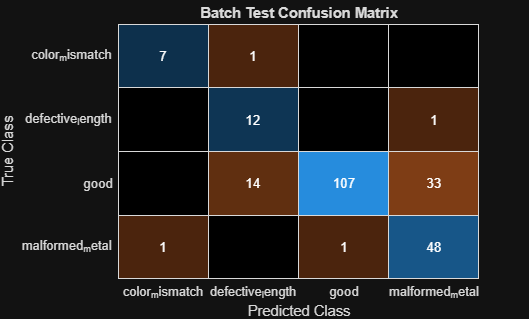

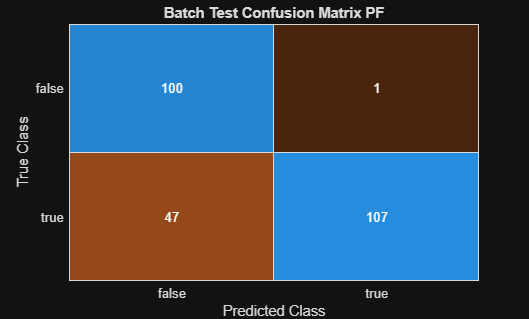

Actual Yield: 68.4%
Predicted Yield 48.0%



Defect Rate: 31.6%
Escaped Defect Rate 1.0%





% Batch image classifier
if performBatchTesting
    % 1. Initialize arrays to store true and predicted labels
    trueLabels = categorical(NaN(1, 255)); 
    predictedLabels = categorical(NaN(1, 255));
    
    % 2. Batch Processing Loop
    % Replace 'numFiles' with the number of test files/iterations
    for i = 1:numFiles
    
        % Load or generate your test data for the current batch
        img = readimage(ds, i); % Define your loading function
    
        % Extract ground truth and pass the data to your trained model
        actual = ds.Labels(i);
        imgData = singleImageInspectionFunction(img, false, true);
    
        % Append results to your master lists
        trueLabels(i) = actual;
        predictedLabels(i) = imgData.AIClass;
    
    end

    % 3. Generate Confusion Chart
    figure;
    cm = confusionchart(trueLabels, predictedLabels);
    cm.Title = 'Batch Test Confusion Matrix';

    % true = pass, false = fail
    truePF = trueLabels == 'good';
    predictedPF = predictedLabels == 'good';

    figure;
    cm = confusionchart(truePF, predictedPF);
    cm.Title = 'Batch Test Confusion Matrix PF';
    % cm.RowSummary = 'row-normalized'; % Shows class-specific true positive rates
    % cm.ColumnSummary = 'column-normalized'; % Shows precision

    % Yield Rates (Actual + Predicted)
    trueYield = sum(truePF) / numFiles * 100;
    predictedYield = sum(predictedPF) / numFiles * 100;
    out = sprintf("Actual Yield: %.1f%%\nPredicted Yield %.1f%%\n", ...
          actualYield, predictedYield);
    disp(out);


    % Defect Rates 
    trueDR = 100 - trueYield; 
    escapedDefects = (predictedPF == true & truePF == false);
    escapedDR = sum(escapedDefects); % Percentage of defects missed by the detection system
    out = sprintf("Defect Rate: %.1f%%\nEscaped Defect Rate %.1f%%\n", ...
        trueDR, escapedDR);
    disp(out);

end